## Problema 1

[x1,y1] = Heun_sistema('PVI1',-1/2,1/2,40,[0 2*exp(-1/2)])

x1 =   -0.500000000000000
  -0.475000000000000
  -0.450000000000000
  -0.425000000000000
  -0.400000000000000
  -0.375000000000000
  -0.350000000000000
  -0.325000000000000
  -0.300000000000000
  -0.275000000000000


y1 =                    0   1.213061319425267
   0.031084696310272   1.273335303734210
   0.063665343630477   1.332621424923750
   0.097714290544725   1.390678929821994
   0.133197759542438   1.447258645671481
   0.170075640838484   1.502103346686908
   0.208301295908526   1.554948165242983
   0.247821371868021   1.605521048665214
   0.288575627846523   1.653543262500176
   0.330496774529580   1.698729941037818


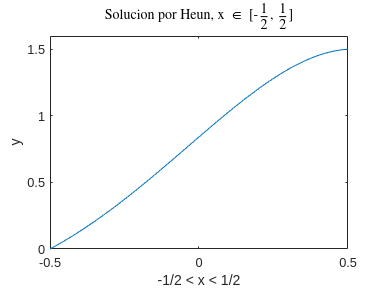


%%% graficar solucion
plot(x1,y1(:,1))
title('Solucion por Heun, x $\in$ [-$\frac{1}{2}$, $\frac{1}{2}$]','Interpreter','latex');
xlabel("-1/2 < x < 1/2")
ylabel('y')

[x2,y2] = runge_kutta('PVI1',-1/2,1/2,40,[0 2*exp(-1/2)])

x2 =   -0.500000000000000
  -0.475000000000000
  -0.450000000000000
  -0.425000000000000
  -0.400000000000000
  -0.375000000000000
  -0.350000000000000
  -0.325000000000000
  -0.300000000000000
  -0.275000000000000


y2 =                    0   1.213061319425267
   0.031081300370381   1.273297020435083
   0.063656600539258   1.332541925292900
   0.097698140969603   1.390555437271618
   0.133172041601720   1.447088568889431
   0.170038096585860   1.501884309365304
   0.208249578755900   1.554678036617806
   0.247753054969931   1.605197974771209
   0.288488213466486   1.653165698036386
   0.330387704405535   1.698296681729947


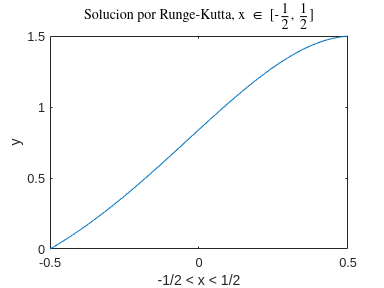

plot(x2,y2(:,1))
title('Solucion por Runge-Kutta, x $\in$ [-$\frac{1}{2}$, $\frac{1}{2}$]','Interpreter','latex');
xlabel("-1/2 < x < 1/2")
ylabel("y")

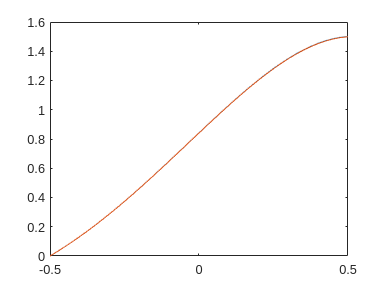

plot(x2,[y1(:,1), y2(:,1)])

%%% Error de convergencia HEUN

max_iter = 7;
n=0:max_iter;
N=40*2.^n;

[x1,y1] = Heun_sistema('PVI1',-1/2,1/2,N(1),[0 2*exp(-1/2)]);
sol1 = y1(:,1);

for j=2:max_iter
    [x1,y2] = Heun_sistema('PVI1',-1/2,1/2,N(j),[0 2*exp(-1/2)]);
    sol2 = y2(:,1);
    errores(j-1)=norm(sol1-sol2(1:2:end));
    sol1 = sol2;
end

relacion = errores(1:end-1)./errores(2:end)

relacion =    2.844912311580307   2.836577716837233   2.832478322242905   2.830446575489658   2.829435296547416


orden = log2(errores(1:end-1)./errores(2:end))

orden =    1.508384185186381   1.504151391651945   1.502064914735170   1.501029693133628   1.500514146285322


%%% Error de convergencia Runge-Kutta

max_iter = 7;
n=0:max_iter;
N=40*2.^n;

[x1,y1] = runge_kutta('PVI1',-1/2,1/2,N(1),[0 2*exp(-1/2)]);
sol1 = y1(:,1);

for j=2:max_iter
    [x1,y2] = runge_kutta('PVI1',-1/2,1/2,N(j),[0 2*exp(-1/2)]);
    sol2 = y2(:,1);
    errores_rk(j-1)=norm(sol1-sol2(1:2:end));
    sol1 = sol2;
end

relacion_rk = errores_rk(1:end-1)./errores_rk(2:end)

relacion_rk =   11.269581103606207  11.293318369480911  11.304418327734068  11.305050540624169  11.504010328873141


orden_rk = log2(errores_rk(1:end-1)./errores_rk(2:end))

orden_rk =    3.494361985643136   3.497397557240392   3.498814854576704   3.498895536737518   3.524064971101217


## Problema 2

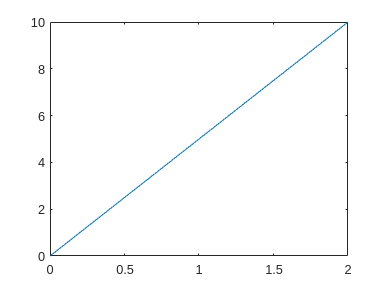

h=0.1;
N = 2/h;

[x,y] = runge_kutta('PVI2', 0, 2, N, [0 0 0 5]);

plot(x,y(:,3))

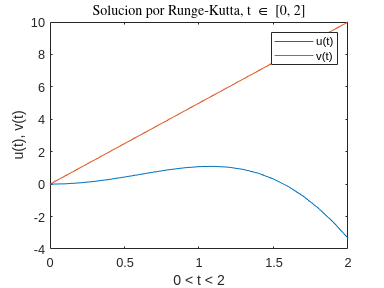

plot(x,y(:,[1 3]))
legend('u(t)','v(t)')
title('Solucion por Runge-Kutta, t $\in$ [0, 2]','Interpreter','latex');
xlabel("0 < t < 2")
ylabel("u(t), v(t)")

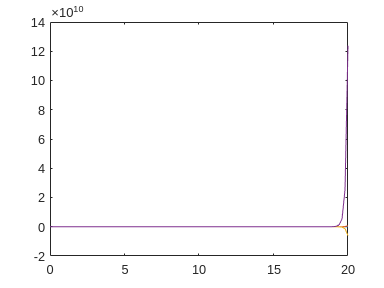

h=0.2;
N = 20/h;

[x2,y2] = runge_kutta('PVI2', 0, 20, N, [0 0 0 5]);
plot(x2,y2)

x = x2(71:end)

x =   14.000000000000000
  14.200000000000001
  14.400000000000000
  14.600000000000001
  14.800000000000001
  15.000000000000000
  15.200000000000001
  15.400000000000000
  15.600000000000001
  15.800000000000001


y = y2(71:end , [1 2])

y = 	1.0e+08 *

   0.000000536190829  -0.000003806392752
  -0.000000253018502  -0.000004060317079
  -0.000001077286879  -0.000004154267733
  -0.000001903215915  -0.000004075284417
  -0.000002695497114  -0.000003817346730
  -0.000003418367377  -0.000003381996089
  -0.000004037158795  -0.000002778646769
  -0.000004519877801  -0.000002024556359
  -0.000004838744470  -0.000001144438544
  -0.000004971621623  -0.000000169713131


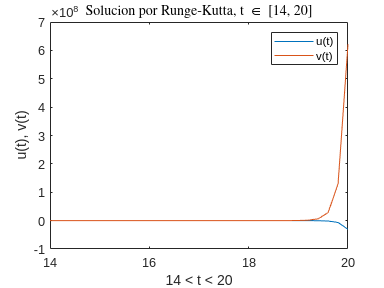


plot(x,y)
legend('u(t)','v(t)')
title('Solucion por Runge-Kutta, t $\in$ [14, 20]','Interpreter','latex');
xlabel("14 < t < 20")
ylabel("u(t), v(t)")